# **Rad229_Flow_Encoding_Gradients.mlx **compares both conventional (analytic) and computional optimization approaches to designing flow compensated and flow encoding gradient waveforms.

## A. Conventional Flow Compensated Slice-Select Gradient

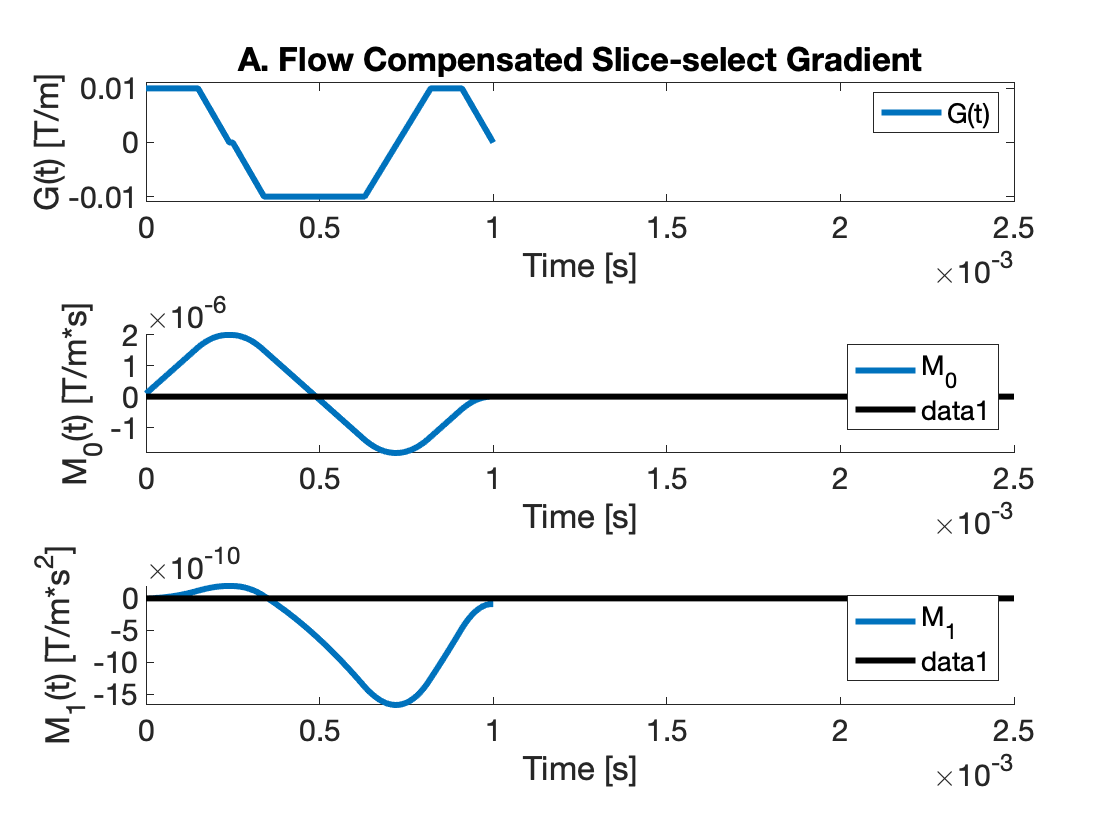

clear params; clear sys;
sys = Rad229_MRI_sys_config;
params.gmax = sys.G_max; % Maximum gradient amplitude, T/m
params.smax = sys.S_max; % Maximum slew rate, T/m/s
params.dt = sys.dt;      % Gradient raster time, s
params.g_ss = 10e-3;     % Slice select gradient amplitude, T/m
params.p_ss = 0.15e-3;   % Slice select gradient plateau, [s]

[G_FC, M0S, M1S, t_ss, G_ss, M0_FC, M1_FC, t_FC] = Rad229_Conventional_FlowComp( params );

figure; hold on;
  subplot( 3 , 1 , 1 ); 
    plot( t_FC , G_FC ); axis( [ 0 2.5e-3 -1.1*sys.G_max 1.1*sys.G_max ] );
    title('A. Flow Compensated Slice-select Gradient');
    xlabel('Time [s]'); ylabel('G(t) [T/m]'); legend('G(t)');
  subplot( 3 , 1 , 2 ); hold on;
    plot( t_FC , M0_FC ); axis([0 2.5e-3 min(M0_FC) max(M0_FC) ] ); 
    xlabel('Time [s]'); ylabel('M_0(t) [T/m*s]'); legend('M_0'); plot( [0 2.5e-3] , [0 0] , 'k');
  subplot( 3 , 1 , 3 ); hold on;
    plot( t_FC , M1_FC ); axis([0 2.5e-3 min(M1_FC) max(M1_FC) ] ); 
    xlabel('Time [s]'); ylabel('M_1(t) [T/m*s^2]'); legend('M_1'); plot( [0 2.5e-3] , [0 0] , 'k');

## B. Conventional Flow Encoded Gradient

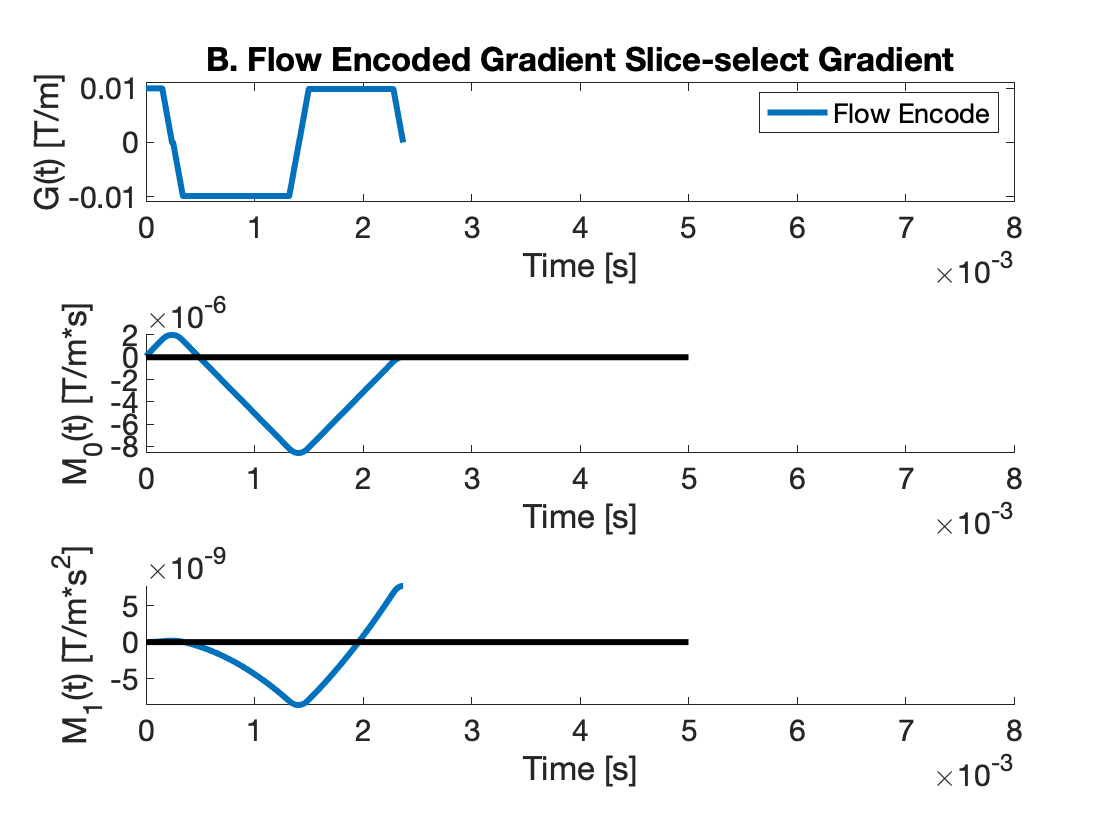

clear params; clear sys;
sys = Rad229_MRI_sys_config;
params.gamma_bar = sys.gamma_bar; 
params.gmax = sys.G_max; % Maximum gradient amplitude, T/m
params.smax = sys.S_max; % Maximum slew rate, T/m/s
params.dt = sys.dt;      % Gradient raster time, s
params.g_ss = 10e-3;     % Slice select gradient amplitude, T/m
params.p_ss = 0.15e-3;   % Slice select gradient plateau, [s]

params.VENC = 1.5;      % Velocity ENCoding strength m/s
% params.VENC = 0.150;      % Velocity ENCoding strength m/s
params.M0S = M0S;       % Slice select M0 (from above)    
params.M1S = M1S;       % Slice select M1 (from above)
params.G_ss = G_ss;     % Slice select gradient (from above)

[G_FE, DeltaM1, M0_FE, M1_FE, t_FE] = Rad229_Conventional_FlowEncode(params);

figure; hold on;
  subplot( 3 , 1 , 1 ); 
    plot( t_FE , G_FE ); axis([0 8e-3 -1.1*sys.G_max 1.1*sys.G_max ]);
    title('B. Flow Encoded Gradient Slice-select Gradient');
    xlabel('Time [s]'); ylabel('G(t) [T/m]'); legend('Flow Encode')
  subplot( 3 , 1 , 2 ); hold on;
    plot( t_FE , M0_FE ); axis([0 8e-3 min(M0_FE) max(M0_FE) ] ); 
    xlabel('Time [s]'); ylabel('M_0(t) [T/m*s]'); plot( [0 5e-3] , [0 0] , 'k'); %legend('M_0'); 
  subplot( 3 , 1 , 3 ); hold on;
    plot( t_FE , M1_FE ); axis([0 8e-3 min(M1_FE) max(M1_FE) ] ); 
    xlabel('Time [s]'); ylabel('M_1(t) [T/m*s^2]'); plot( [0 5e-3] , [0 0] , 'k'); %legend('M_1'); 

## C. Compare Conventional Flow Compensated/Encoded

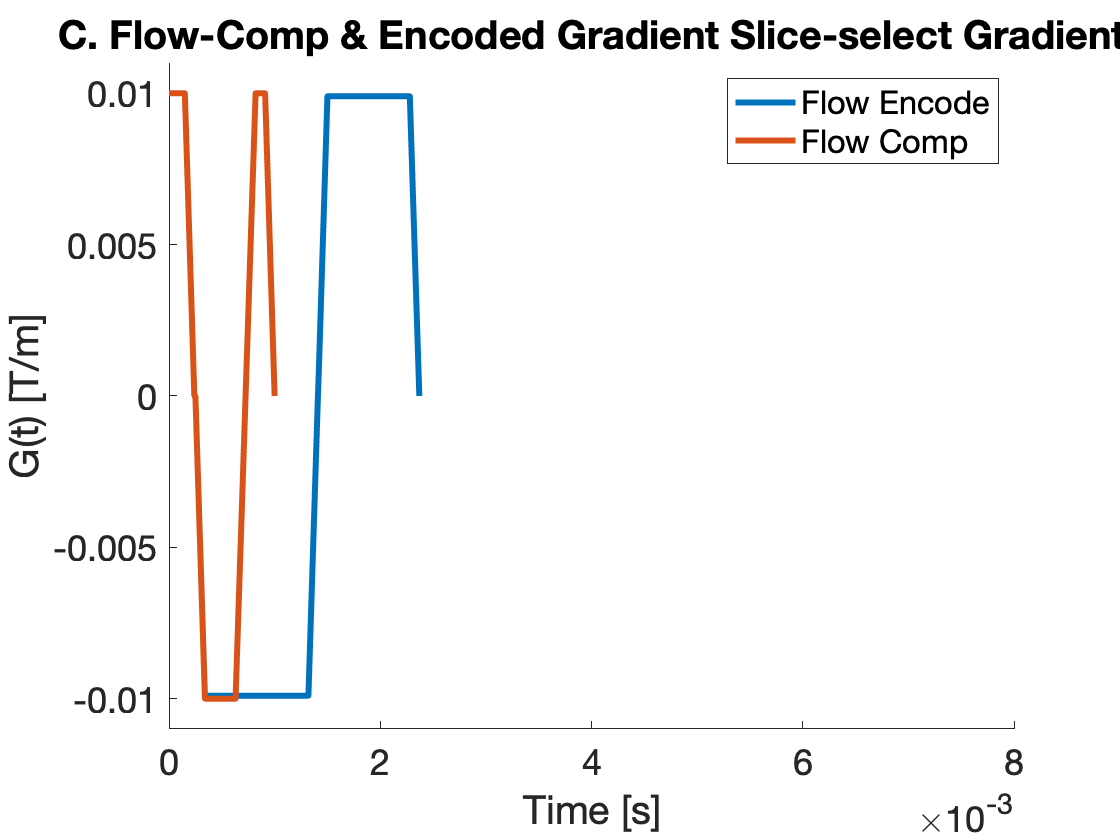

figure; hold on;
  plot( t_FE , G_FE ); plot( t_FC , G_FC );   axis([0 8e-3 -1.1*sys.G_max 1.1*sys.G_max ]);
  title('C. Flow-Comp & Encoded Gradient Slice-select Gradient');
  xlabel('Time [s]'); ylabel('G(t) [T/m]'); legend('Flow Encode','Flow Comp');

## D. Optimized Asymmetric Flow Encoding Gradients

% This code has a linear (not a bisection) search for the optimal alpha, which is slow!
clear params;
params.mode = 'free';
params.gmax = sys.G_max; % Maximum gradient amplitude [T/m]
params.smax = sys.S_max; % Maximum slew rate [T/m/s]
params.dt = sys.dt;      % Gradient raster time [s]
params.g_ss = 10e-3;     % Slice select gradient amplitude [T/m]
params.p_ss = 0.15e-3;   % Slice select gradient plateau [s]

[G_FC, M0S, M1S, t_ss, G_ss] = Rad229_Conventional_FlowComp(params);

params.VENC = 1.5;      % Velocity ENCoding strength m/s
% params.VENC = 0.150;      % Velocity ENCoding strength m/s
params.M0S = M0S;       % Slice select M0 (from above)
params.M1S = M1S;       % Slice select M1 (from above)
params.G_ss = G_ss;     % Slice select gradient (from above)

t_vec = ( 0 : (length(G_ss)-1) ) * params.dt;

GAM = 2*pi*42.57e6;       % rad/(s*T)
DeltaM1 = pi/(GAM*params.VENC);  % T/m x s^2

for i = 0:0.1:0.5   % Loop over possible values of alpha
  
  alpha = i;
  params.moment_params = [];
  params.moment_params(:,end+1) = [0, 0, t_ss, -1, -1, 1e6*-M0S(1,end), 1.0e-3];                   % Target M0
  params.moment_params(:,end+1) = [0, 1, t_ss, -1, -1, 1e9*(-M1S(1,end)+(DeltaM1*alpha)), 1.0e-3];   % Target M1
  [G1, T1] = get_min_TE_free(params, 5.0);
  G_FE_pos = horzcat(G_ss,G1);
  
  params.moment_params = [];
  params.moment_params(:,end+1) = [0, 0, t_ss, -1, -1, 1e6*-M0S(1,end), 1.0e-3];                       % Target M0
  params.moment_params(:,end+1) = [0, 1, t_ss, -1, -1, 1e9*(-M1S(1,end)-(DeltaM1*(1-alpha))), 1.0e-3];   % Target M1
  params.TE = T1;
  [G2, debug] = gropt(params);
  T2 = length(G2)*params.dt*1000;
  G_FE_neg = horzcat(G_ss,G2);
  
  if abs(T1-T2) <= 0.01 && debug == 0   % Stop when the waveforms are equal and constraints met
    break
  end
  
end

Testing TE = 2.500 1.250 0.625 0.938 0.781 0.859 0.820 0.801 0.811 0.815 0.813 Final TE = 0.815 ms
Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 1.055 1.074 1.064 1.069 1.067 Final TE = 1.067 ms
Testing TE = 2.500 1.250 1.875 1.562 1.406 1.328 1.289 1.270 1.260 1.255 1.257 Final TE = 1.257 ms
Testing TE = 2.500 1.250 1.875 1.562 1.406 1.328 1.367 1.387 1.396 1.401 1.404 Final TE = 1.406 ms


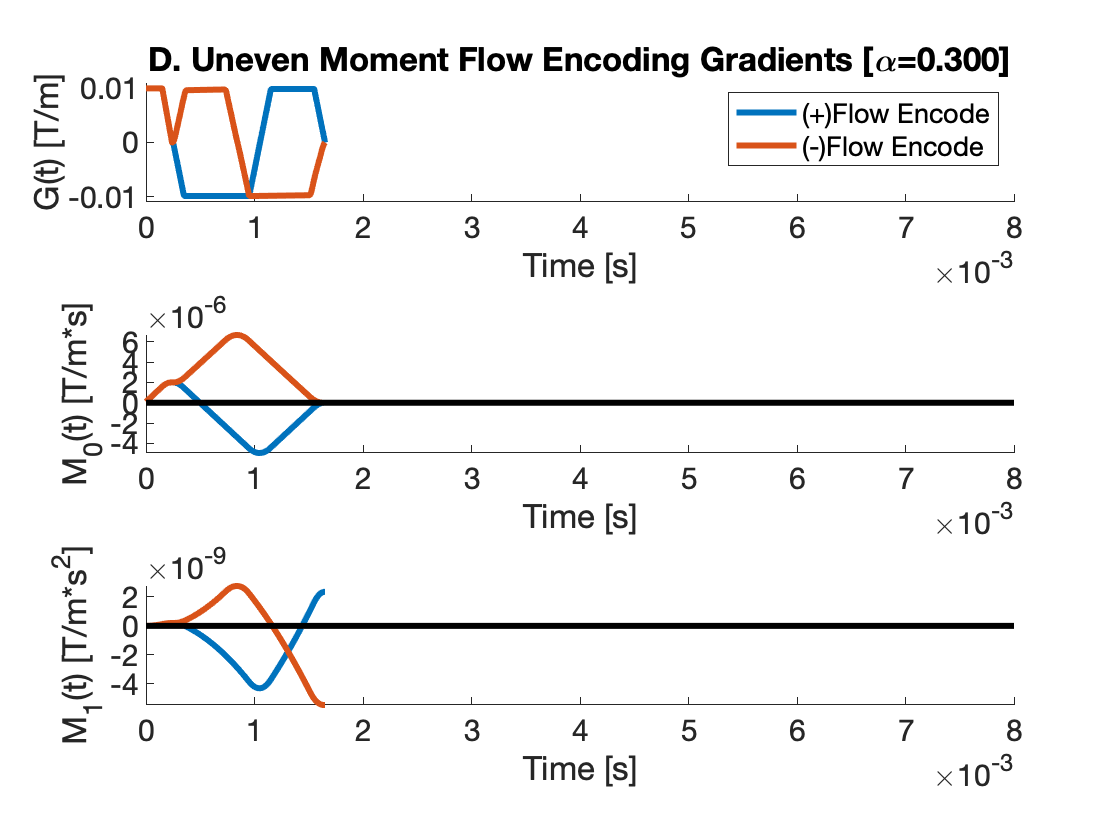


% Define some time and moment vectors
tFE_pos = (0 : (length(G_FE_pos) - 1) ) * params.dt;
tFE_neg = (0 : (length(G_FE_neg) - 1) ) * params.dt;

M0_FE_pos = cumsum( ( G_FE_pos .* params.dt ) , 2 );           % [T/m x s]
M1_FE_pos = cumsum( ( G_FE_pos .* tFE_pos * params.dt ) , 2);  % [T/m x s^2]

M0_FE_neg = cumsum( ( G_FE_neg .* params.dt ) , 2 );           % [T/m x s]
M1_FE_neg = cumsum( ( G_FE_neg .* tFE_neg * params.dt ) , 2);  % [T/m x s^2]

% Define some limits
M0_min = min ( [min(M0_FE_pos) min(M0_FE_neg)] ); M0_max = max ( [max(M0_FE_pos) max(M0_FE_neg)] );
M1_min = min ( [min(M1_FE_pos) min(M1_FE_neg)] ); M1_max = max ( [max(M1_FE_pos) max(M1_FE_neg)] );

% Generate a figure
figure; hold on;
  subplot( 3 , 1 , 1 ); hold on;
    plot( tFE_pos , G_FE_pos ); plot( tFE_neg , G_FE_neg );  axis([0 8e-3 -1.1*sys.G_max 1.1*sys.G_max]);
    title(['D. Uneven Moment Flow Encoding Gradients [\alpha=' , num2str(alpha,'%.3f') , ']']);
    xlabel('Time [s]'); ylabel('G(t) [T/m]'); legend('(+)Flow Encode','(-)Flow Encode');
  subplot( 3 , 1 , 2 ); hold on;
    plot( tFE_pos , M0_FE_pos ); axis([0 8e-3 M0_min M0_max ] ); 
    plot( tFE_neg , M0_FE_neg ); axis([0 8e-3 M0_min M0_max ] ); 
    xlabel('Time [s]'); ylabel('M_0(t) [T/m*s]'); plot( [0 8e-3] , [0 0] , 'k'); %legend('M_0'); 
  subplot( 3 , 1 , 3 ); hold on;
    plot( tFE_pos , M1_FE_pos ); axis([0 8e-3 M1_min M1_max ] ); 
    plot( tFE_neg , M1_FE_neg ); axis([0 8e-3 M1_min M1_max ] ); 
    xlabel('Time [s]'); ylabel('M_1(t) [T/m*s^2]'); plot( [0 8e-3] , [0 0] , 'k'); %legend('M_0');